Baudrate = 115200;
serialportlist

Undefined function or variable 'serialportlist'.

RpLidar = serialport("COM3", Baudrate, "Timeout", 1, "Parity","odd")
setDTR(RpLidar,false)







% Reset (leave protected mode)
resetStr = 'A540'
resetStrData = sscanf(resetStr, '%2x')
write(RpLidar,resetStrData,"uint8")
readReset = read(RpLidar, 5, "uint8")
dec2hex(readReset)


% Start scan
startStr = 'A521'
startStrData = sscanf(startStr, '%2x')
write(RpLidar,startStr,"uint8")
scandata = read(RpLidar, 59, "uint8")
RpLidar.NumBytesAvailable
dec2bin(scandata, 8)
dec2hex(scandata)

%flush(RpLidar, "output")


% Disconnect
clear RpLidar


stopStr = 'A525'
stopStrData = sscanf(stopStr, '%2x')
write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")
dec2hex(readStop)

% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

write(RpLidar, data, "uint8");
readData = read(RpLidar, 10,"uint8");
hexStr = dec2hex(readData)


getInfoStr = 'A550'
getInfoStrData = sscanf(getInfoStr, '%2x')
write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")
hexStr = dec2hex(readInfo)


start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges


angles = linspace(-pi/2, pi/2, numel(ranges))
scan = lidarScan(ranges, angles)
plot(scan)



start = randi([45, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end



theta = linspace(0, 360, 360)

theta =          0    1.0028    2.0056    3.0084    4.0111    5.0139    6.0167    7.0195    8.0223    9.0251   10.0279   11.0306   12.0334   13.0362   14.0390   15.0418   16.0446   17.0474   18.0501   19.0529   20.0557   21.0585   22.0613   23.0641   24.0669   25.0696   26.0724   27.0752   28.0780   29.0808   30.0836   31.0864   32.0891   33.0919   34.0947   35.0975   36.1003   37.1031   38.1058   39.1086   40.1114   41.1142   42.1170   43.1198   44.1226   45.1253   46.1281   47.1309   48.1337   49.1365


rho = randi([0, 10], 360, 1)

rho =      9
     4
     7
     2
     0
     6
     7
     3
     6
     3


theta_rad = deg2rad(theta)

theta_rad =          0    0.0175    0.0350    0.0525    0.0700    0.0875    0.1050    0.1225    0.1400    0.1575    0.1750    0.1925    0.2100    0.2275    0.2450    0.2625    0.2800    0.2975    0.3150    0.3325    0.3500    0.3675    0.3850    0.4025    0.4200    0.4375    0.4550    0.4726    0.4901    0.5076    0.5251    0.5426    0.5601    0.5776    0.5951    0.6126    0.6301    0.6476    0.6651    0.6826    0.7001    0.7176    0.7351    0.7526    0.7701    0.7876    0.8051    0.8226    0.8401    0.8576


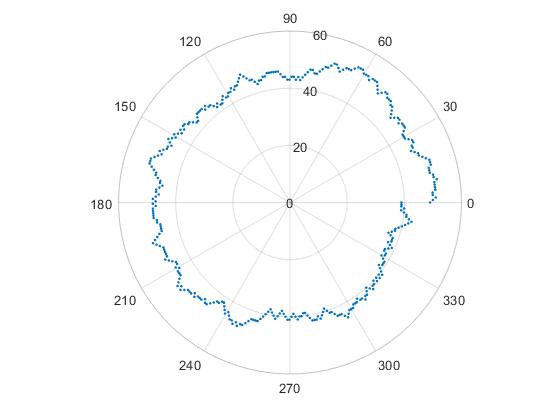

polarplot(theta_rad, ranges, '.')

## Shape generator v1 square

x_v1 = ones(1,45) * 20;
x_v2 = linspace(20, -20, 90);
x_v3 = ones(1, 90) * (-20);
x_v4 = linspace(-20, 20, 90);
x_v5 = ones(1,45) * 20;
x_square = [x_v1 x_v2 x_v3 x_v4 x_v5];

y_v1 = linspace(0, 20, 45);
y_v2 = ones(1,90) * 20;
y_v3 = linspace(20, -20, 90);
y_v4 = ones(1,90) * (-20);
y_v5 = linspace(-20, 0, 45);
y_square = [y_v1 y_v2 y_v3 y_v4 y_v5];

## Transform into polar coordinates

[theta_square, rho_square] = cart2pol(x_square, y_square)

theta_square =          0    0.0227    0.0454    0.0681    0.0907    0.1132    0.1355    0.1578    0.1799    0.2018    0.2235    0.2450    0.2663    0.2873    0.3081    0.3286    0.3488    0.3687    0.3883    0.4076    0.4266    0.4453    0.4636    0.4817    0.4993    0.5167    0.5337    0.5504    0.5667    0.5827    0.5984    0.6138    0.6288    0.6435    0.6579    0.6720    0.6857    0.6992    0.7124    0.7252    0.7378    0.7501    0.7621    0.7739    0.7854    0.7854    0.7968    0.8084    0.8203    0.8324


rho_square =    20.0000   20.0052   20.0207   20.0464   20.0825   20.1287   20.1851   20.2515   20.3279   20.4141   20.5100   20.6155   20.7305   20.8547   20.9880   21.1303   21.2813   21.4409   21.6088   21.7850   21.9692   22.1611   22.3607   22.5676   22.7818   23.0029   23.2308   23.4653   23.7062   23.9533   24.2064   24.4654   24.7299   25.0000   25.2753   25.5558   25.8412   26.1314   26.4263   26.7256   27.0292   27.3370   27.6489   27.9647   28.2843   28.2843   27.9683   27.6560   27.3475   27.0430


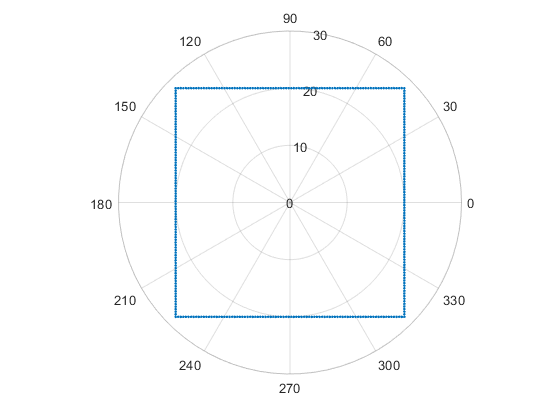


figure
polarplot(theta_square, rho_square, '.')
hold on

## Obstacle detection

detection_range = 21

detection_range = 21

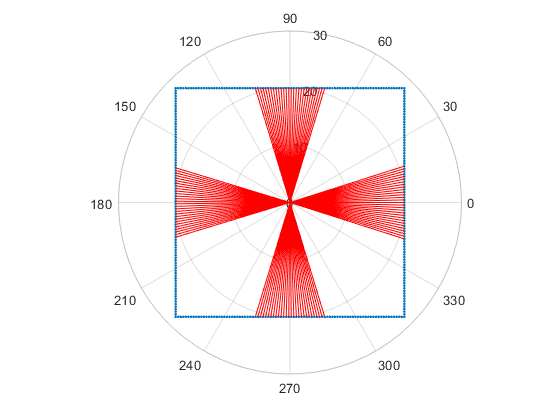

for i = 1:360
    if  abs(rho_square(i)) <= detection_range
        line_angle = [theta_square(i) theta_square(i)];
        line_range = [0 rho_square(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off